
Testing BC neuron sweep: N_hidden=1000 (1/6), network seed=1.


Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\classification_BC_gpu_N01000_primary_seed001_gpu_test_analysis_20260718_182723_499.mat


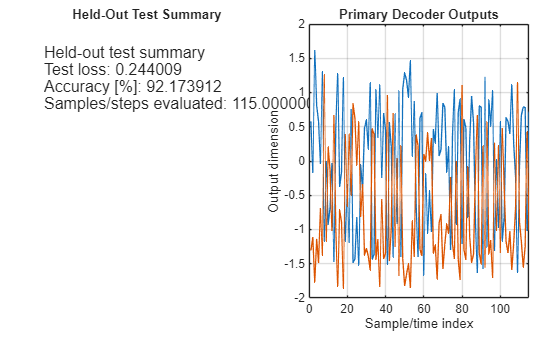

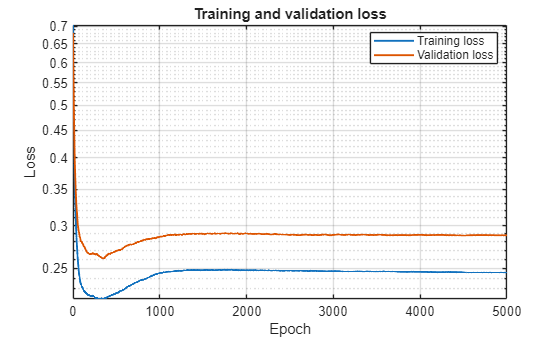

      loss: 0.2440
    metric: 92.1739
     count: 115
         Z: [2×115 single]
         Y: [2×115 single]




Testing BC neuron sweep: N_hidden=2000 (2/6), network seed=1.


Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\classification_BC_gpu_N02000_primary_seed001_gpu_test_analysis_20260718_182726_771.mat


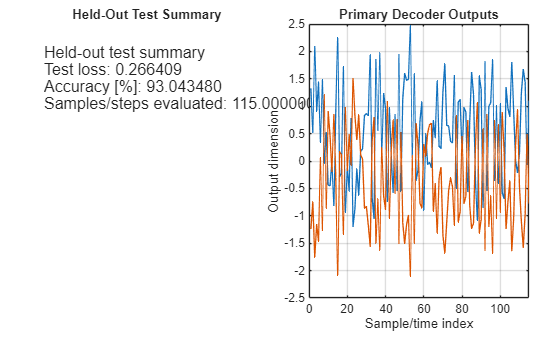

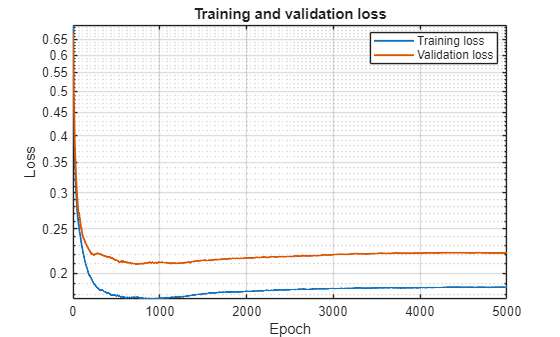

      loss: 0.2664
    metric: 93.0435
     count: 115
         Z: [2×115 single]
         Y: [2×115 single]




Testing BC neuron sweep: N_hidden=4000 (3/6), network seed=1.


Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\classification_BC_gpu_N04000_primary_seed001_gpu_test_analysis_20260718_182730_717.mat


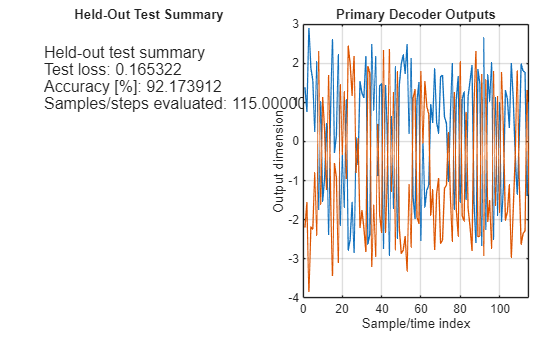

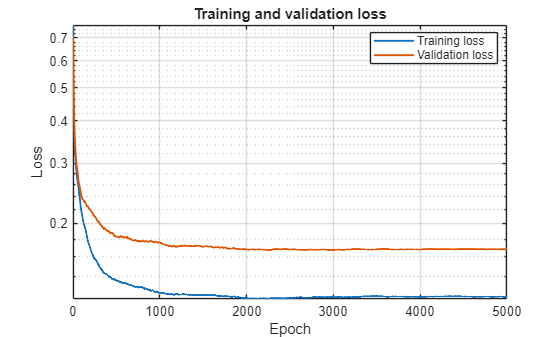

      loss: 0.1653
    metric: 92.1739
     count: 115
         Z: [2×115 single]
         Y: [2×115 single]




Testing BC neuron sweep: N_hidden=8000 (4/6), network seed=1.


Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\classification_BC_gpu_N08000_primary_seed001_gpu_test_analysis_20260718_182736_758.mat


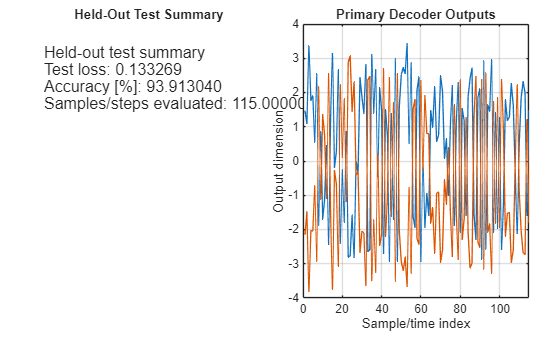

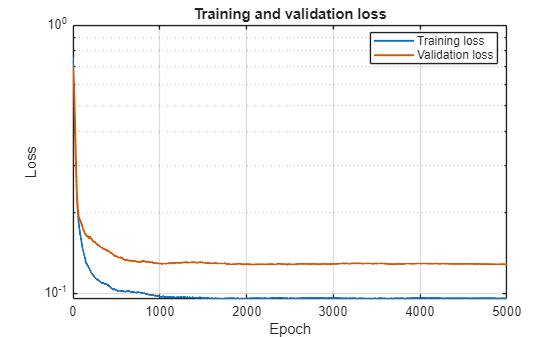

      loss: 0.1333
    metric: 93.9130
     count: 115
         Z: [2×115 single]
         Y: [2×115 single]




Testing BC neuron sweep: N_hidden=16000 (5/6), network seed=1.


Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\classification_BC_gpu_N16000_primary_seed001_gpu_test_analysis_20260718_182746_230.mat


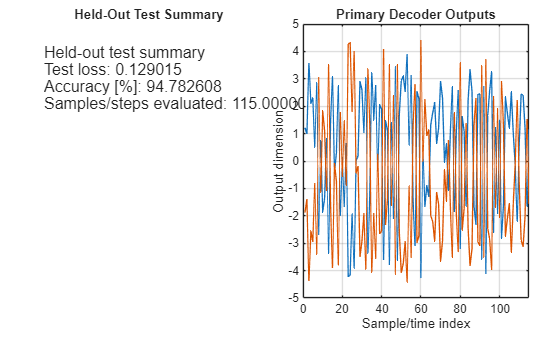

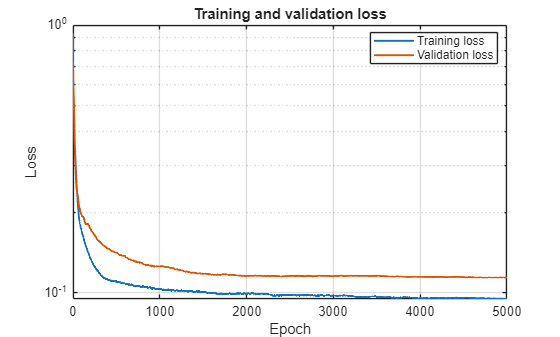

      loss: 0.1290
    metric: 94.7826
     count: 115
         Z: [2×115 single]
         Y: [2×115 single]




Testing BC neuron sweep: N_hidden=32000 (6/6), network seed=1.


Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\classification_BC_gpu_test_analysis_20260718_182802_844.mat


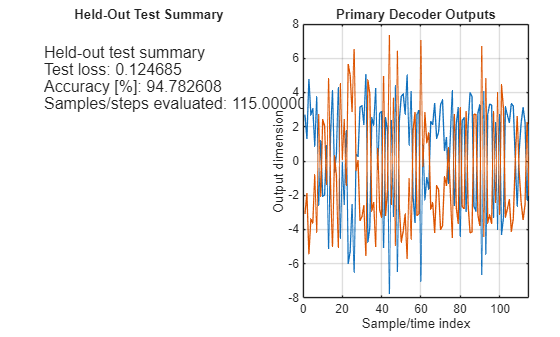

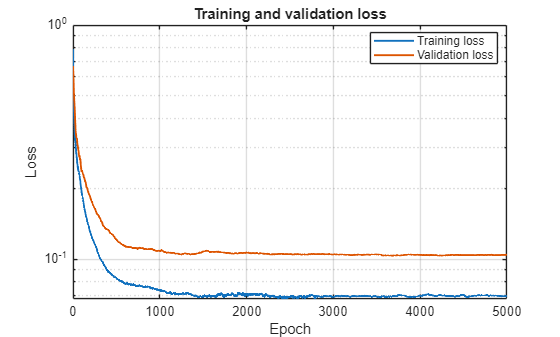

      loss: 0.1247
    metric: 94.7826
     count: 115
         Z: [2×115 single]
         Y: [2×115 single]



% Package orientation: Local held-out test wrapper for the breast-cancer neuron-count sweep.

% TEST_GPU_implementation_classification_BC_neuron_sweep.mlx
% Test seed 1 breast-cancer models with 1k, 2k, 4k, 8k, 16k and 32k neurons.
% Every network is evaluated on the complete held-out test split.

clear; clc;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);

%% ---------------- Test Configuration ----------------
neuron_counts = [1000 2000 4000 8000 16000 32000];
network_seed = 1;
test_backend = 'gpu';
batch_size = 32;
save_publication_analysis = true;
publication_static_rate_batch_size = 32;
plot_test_summary = true;
run_spike_diagnostics = false; % Publication export already computes full-test firing rates.
diagnostic_max_samples = 8; % Set to Inf for a full-test CPU diagnostic replay.
save_diagnostic_files = false;

%% ---------------- Resolve and Validate Models ----------------
model_dir = fullfile(repo_root, 'outputs', 'models');
model_files = cell(size(neuron_counts));
for ii = 1:numel(neuron_counts)
    N_hidden = neuron_counts(ii);
    if N_hidden == 32000
        model_files{ii} = fullfile(model_dir, sprintf( ...
            'classification_BC_gpu_primary_seed%03d.mat', network_seed));
    else
        model_files{ii} = fullfile(model_dir, sprintf( ...
            'classification_BC_gpu_N%05d_primary_seed%03d.mat', N_hidden, network_seed));
    end
    if exist(model_files{ii}, 'file') ~= 2
        error('BC neuron-sweep model is missing for N_hidden=%d: %s', N_hidden, model_files{ii});
    end
    saved = load_training_result(model_files{ii});
    if ~isfield(saved, 'options') || ~isfield(saved.options, 'N_hidden') || ...
            double(saved.options.N_hidden) ~= N_hidden
        error('BC model metadata does not match N_hidden=%d: %s', N_hidden, model_files{ii});
    end
    if ~isfield(saved.options, 'task_tag') || ~strcmpi(char(saved.options.task_tag), 'bc')
        error('Expected a breast-cancer model for N_hidden=%d: %s', N_hidden, model_files{ii});
    end
end

%% ---------------- Run Full Held-Out Tests ----------------
results = cell(size(neuron_counts));
test_accuracies = nan(size(neuron_counts));
test_losses = nan(size(neuron_counts));
for ii = 1:numel(neuron_counts)
    N_hidden = neuron_counts(ii);
    model_file = model_files{ii};
    opts = struct('model_file', model_file, 'batch_size', batch_size, ...
        'save_publication_analysis', save_publication_analysis, ...
        'publication_static_rate_batch_size', publication_static_rate_batch_size);

    fprintf('\nTesting BC neuron sweep: N_hidden=%d (%d/%d), network seed=%d.\n', ...
        N_hidden, ii, numel(neuron_counts), network_seed);
    result = snn_primary_api('test_static', 'classification', test_backend, opts);
    result.neuron_count = N_hidden;
    results{ii} = result;
    test_losses(ii) = double(result.test.loss);
    test_accuracies(ii) = double(result.test.metric);
    if plot_test_summary, snn_plot_test_result(result); end

    if run_spike_diagnostics
        diag_dir = fullfile(repo_root, 'outputs', 'diagnostics', ...
            sprintf('classification_BC_N%05d_test_gpu', N_hidden));
        if save_diagnostic_files && exist(diag_dir, 'dir') ~= 7, mkdir(diag_dir); end
        diag_opts = struct('model_file', model_file, 'output_dir', diag_dir, ...
            'save_files', save_diagnostic_files, 'max_samples', diagnostic_max_samples);
        diag = snn_primary_api('spike_diagnostics_static', 'classification', 'cpu', diag_opts);
        fprintf('N=%d active neurons: %.2f%%%% (%d/%d); silent neurons: %.2f%%%% (%d/%d).\n', ...
            N_hidden, diag.active_neuron_percent, diag.active_neuron_count, diag.n_neurons, ...
            diag.silent_neuron_percent, diag.silent_neuron_count, diag.n_neurons);
    end
    disp(result.test);
end


summary_table = table(neuron_counts(:), test_losses(:), test_accuracies(:), ...
    'VariableNames', {'N_hidden', 'TestLoss', 'AccuracyPercent'});
disp(summary_table);

    N_hidden    TestLoss    AccuracyPercent
    ________    ________    _______________

      1000      0.24401         92.174     
      2000      0.26641         93.043     
      4000      0.16532         92.174     
      8000      0.13327         93.913     
     16000      0.12901         94.783     
     32000      0.12469         94.783     



fprintf('Completed full held-out breast-cancer neuron-sweep tests.\n');

Completed full held-out breast-cancer neuron-sweep tests.
